clear, close all, clc

h5disp("gammaray_lab4.h5");

HDF5 gammaray_lab4.h5 
Group '/' 
    Dataset 'data' 
        Size:  25920001x4
        MaxSize:  25920001x4
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


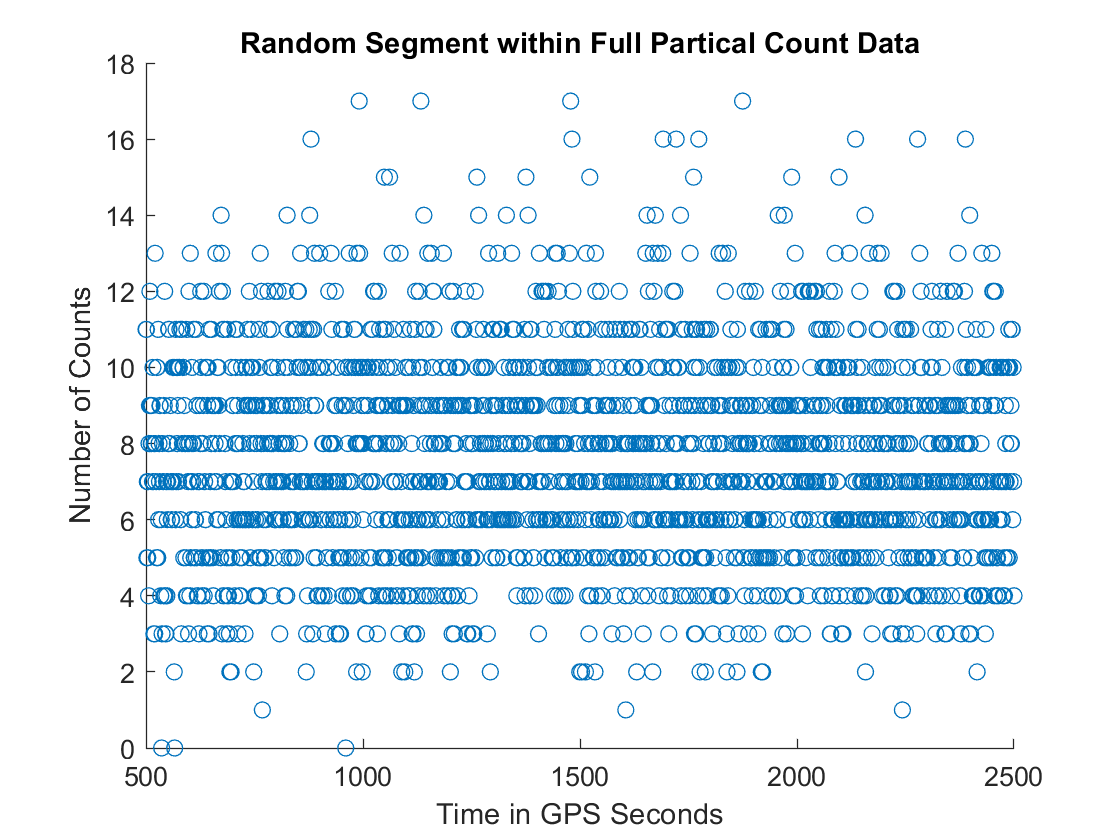


mydata = h5read("gammaray_lab4.h5",'/data');

x1 = mydata(:,4); %Partical Counts
x2 = mydata(:,3); %Earth Longitude
x3 = mydata(:,2); %Solar Phase
x4 = mydata(:,1); %Time

plot_scat([500,2000],x1)
title('Random Segment within Full Partical Count Data')
xlabel('Time in GPS Seconds')
ylabel('Number of Counts')

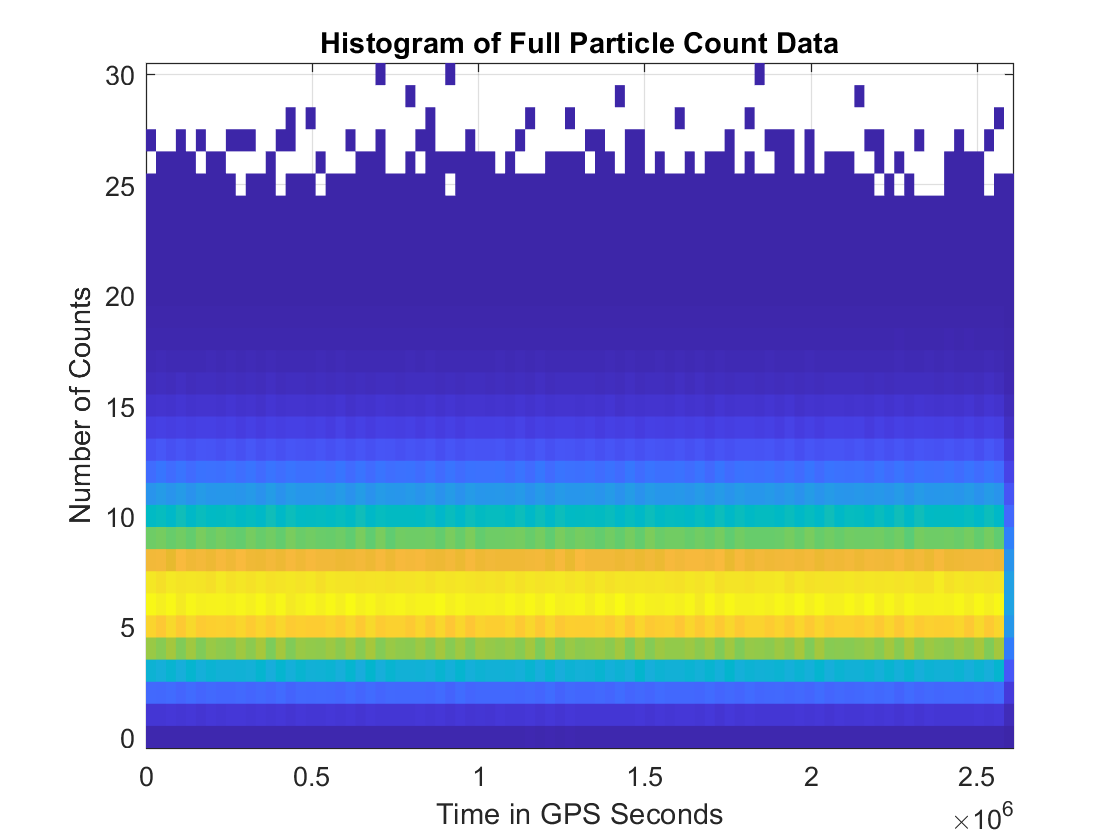


t = linspace(1,2592000,length(x1))';
histogram2(t,x1,'DisplayStyle', 'tile')
title('Histogram of Full Particle Count Data')
xlabel('Time in GPS Seconds')
ylabel('Number of Counts')

At a high level the average number or particle counts per 0.1 seconds seems to be around 6. We can see from plotting the partical count against the longitudinal position of the SC that the background exponentially decays to around 5. In order to make a background pdf I will make the mean exponentially decay based initially on the logitudinal position which is based on time.

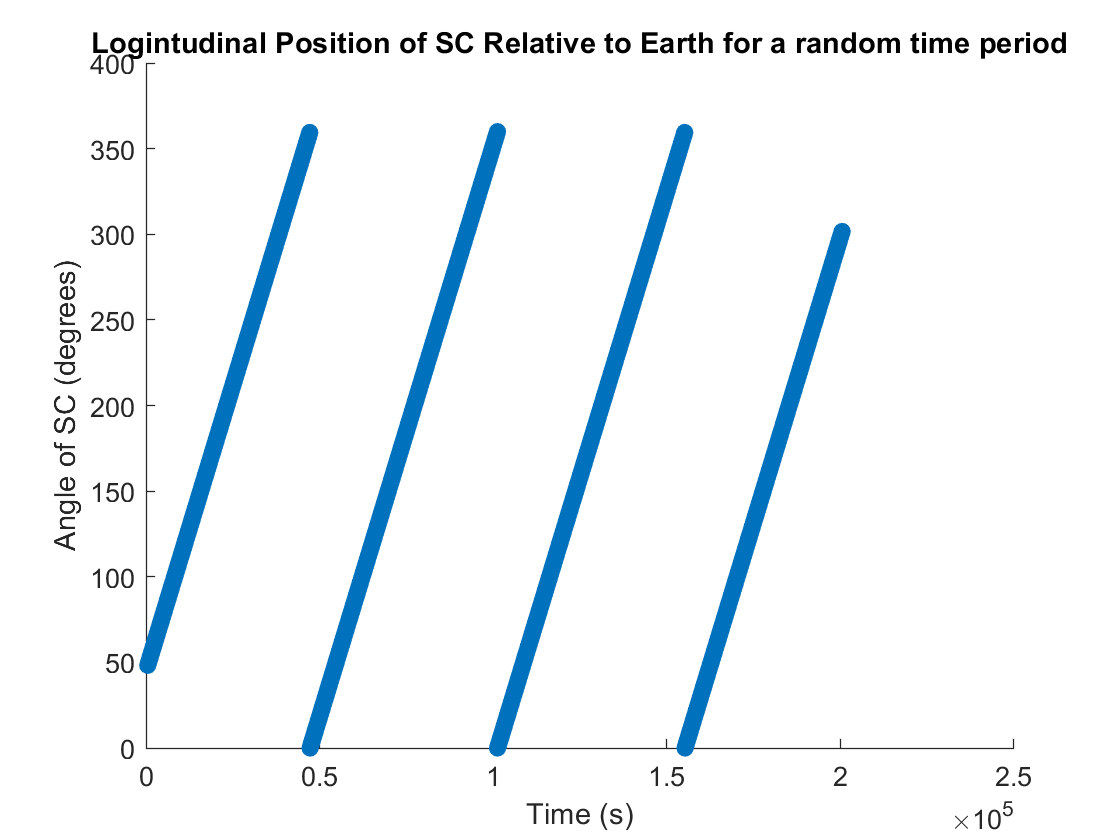

plot_scat([500,200000],x2)
title('Logintudinal Position of SC Relative to Earth for a random time period')
xlabel('Time (s)')
ylabel('Angle of SC (degrees)')

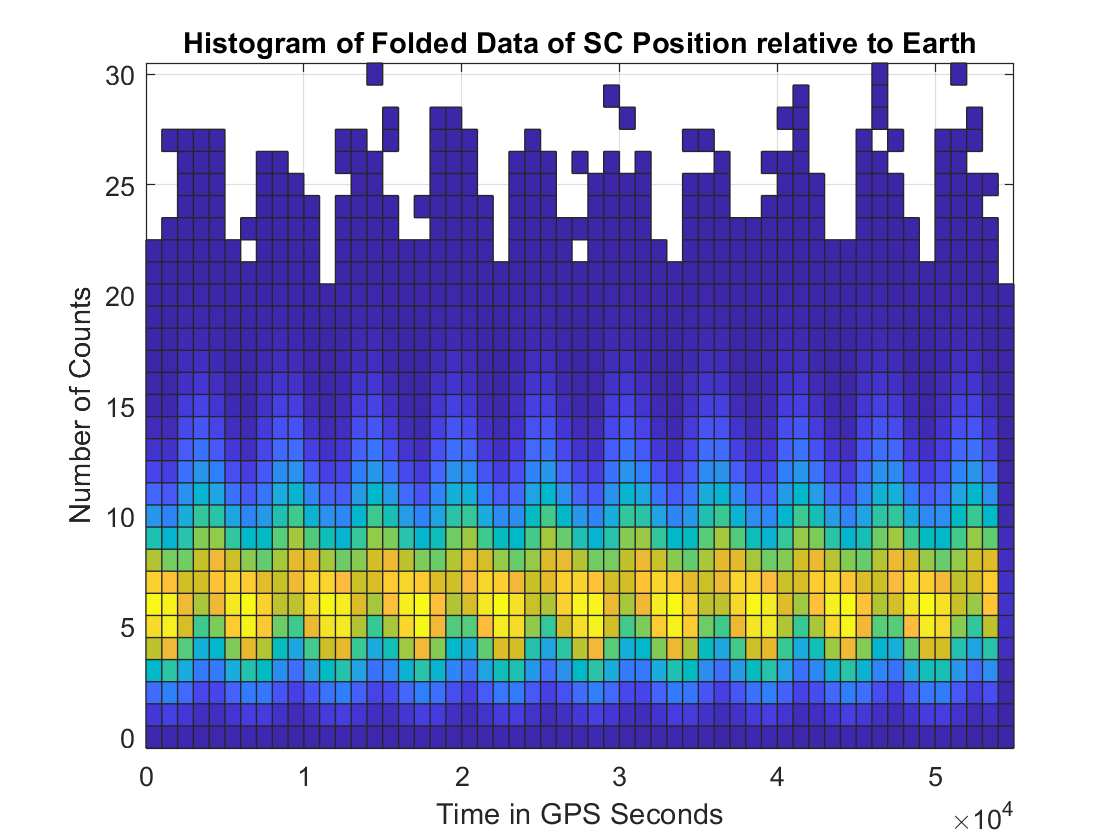


b1 = mod(t,54050);
histogram2(b1,x1,'DisplayStyle', 'tile')
title('Histogram of Folded Data of SC Position relative to Earth')
xlabel('Time in GPS Seconds')
ylabel('Number of Counts')

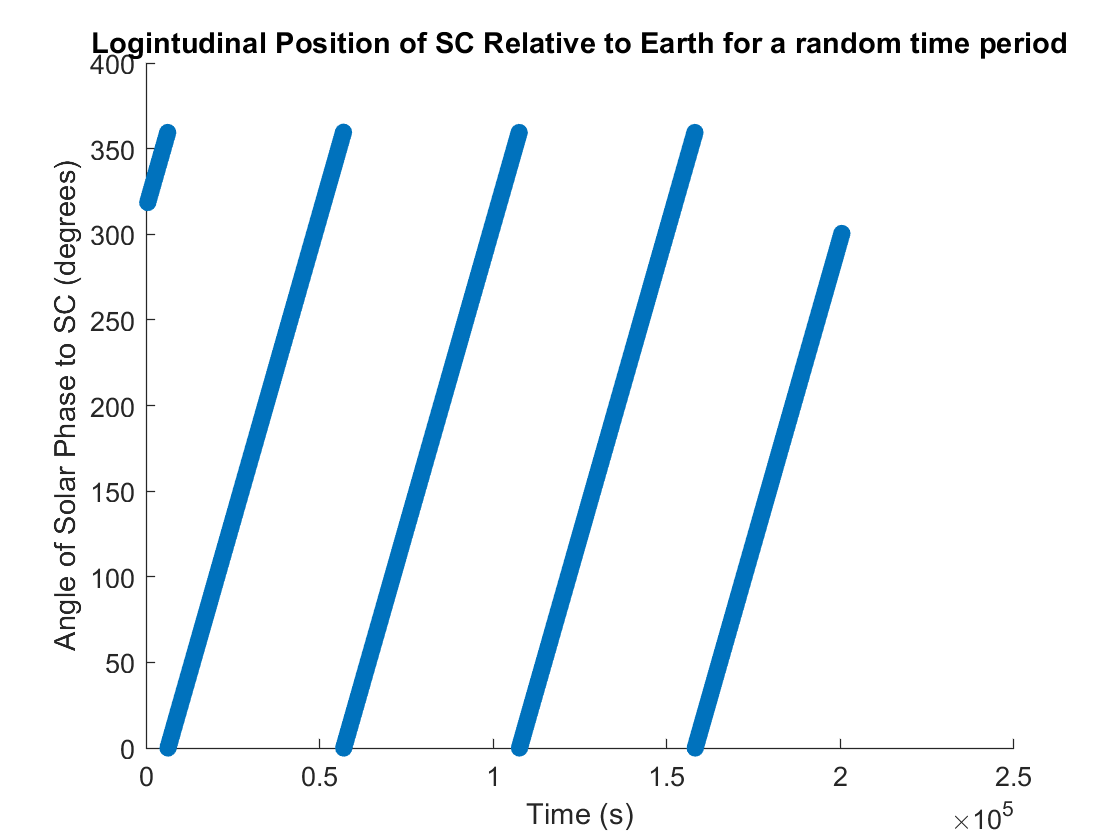


plot_scat([500,200000],x3)
title('Logintudinal Position of SC Relative to Earth for a random time period')
xlabel('Time (s)')
ylabel('Angle of Solar Phase to SC (degrees)')

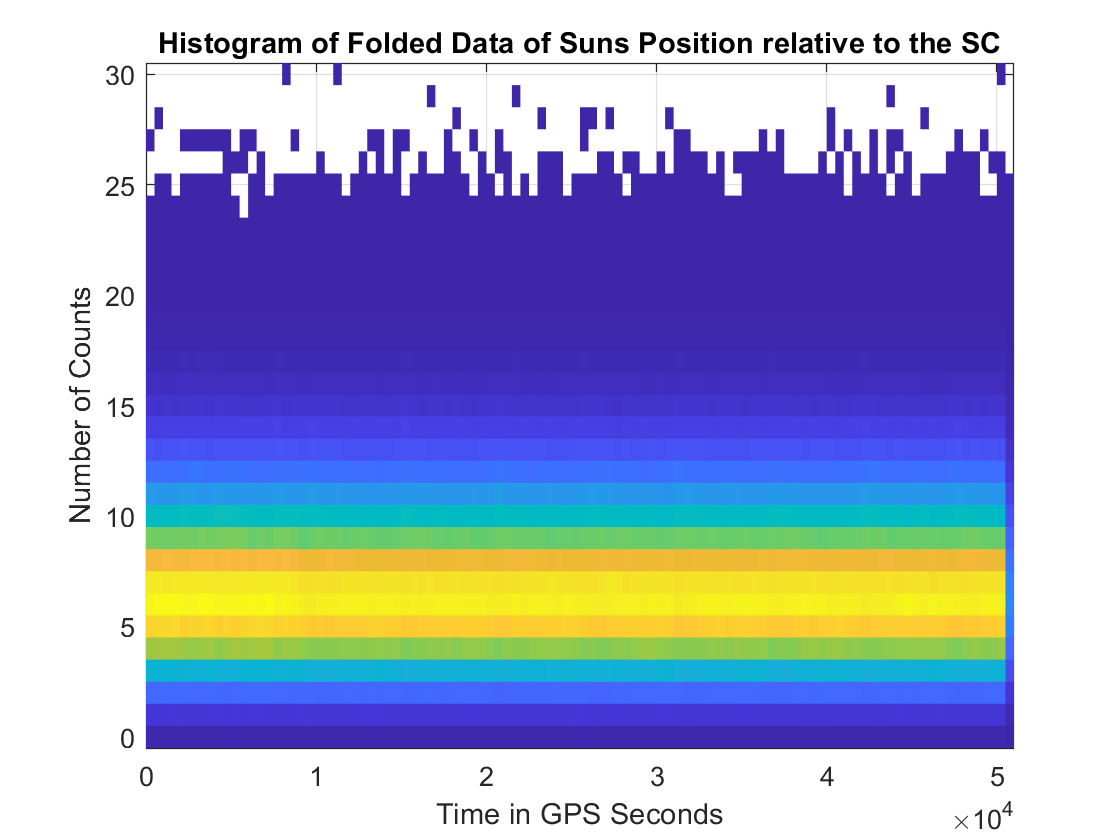


b2 = mod(t,50650);
histogram2(b2,x1,'DisplayStyle', 'tile')
title('Histogram of Folded Data of Suns Position relative to the SC')
xlabel('Time in GPS Seconds')
ylabel('Number of Counts')

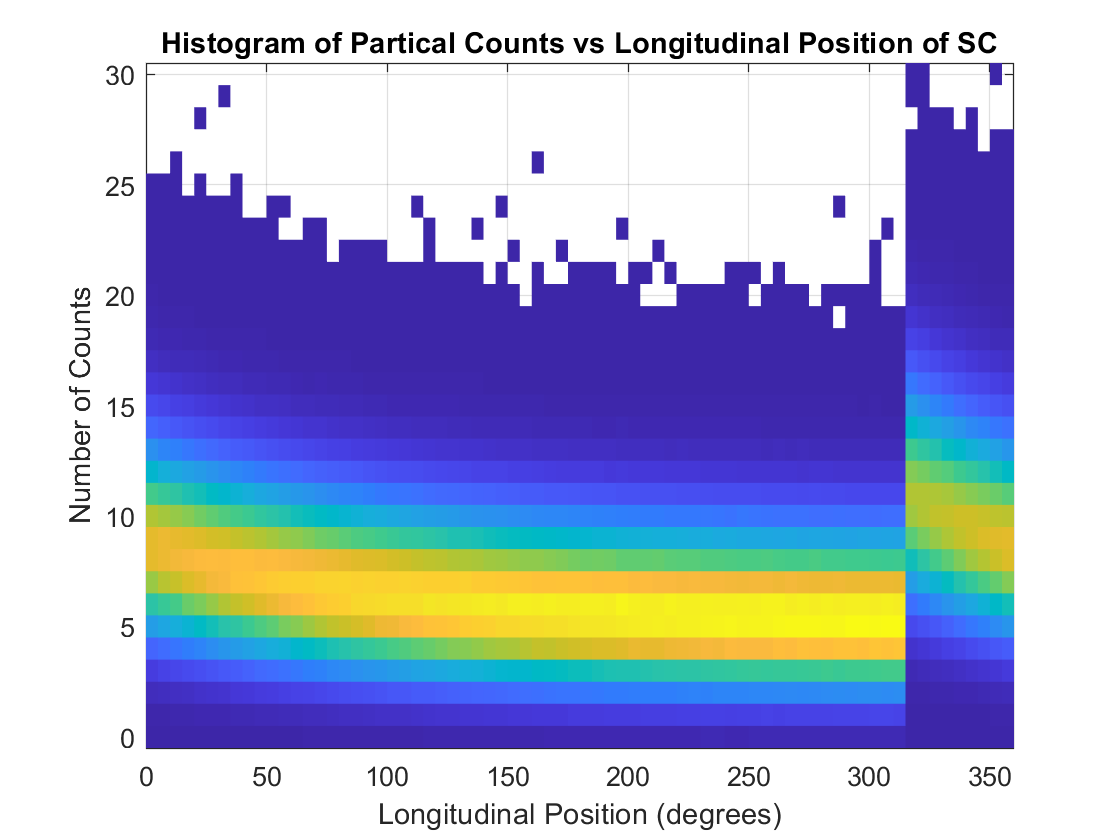


histogram2(x2,x1,'DisplayStyle', 'tile')
title('Histogram of Partical Counts vs Longitudinal Position of SC')
xlabel('Longitudinal Position (degrees)')
ylabel('Number of Counts')


for i = 1:length(x2)
    if x2(i) < 315
        x2(i) = x2(i)+360;
    end
end

histogram2(x2,x1,'DisplayStyle', 'tile')
title('Shifted Histogram of Partical Counts vs Longitudinal Position of SC')
xlabel('Longitudinal Position (degrees)')
ylabel('Number of Counts')
hold on

mean = @(t) (1/1.015).^(t-435)+5;
mean_curvefit = @(t) 17.81*exp(-0.001901*t);

scatter(x2,mean(x2),'Linewidth',4)


The exponential equation I used to model the mean is $mean(x) = \frac{1}{1.015}^{x-435}+5$ where $x=$logitudinal position of the SC relative to the earth. The longitudinal position is also based on time as the SC will need to be going a constant radial speed in order to maintain the same orbit. 

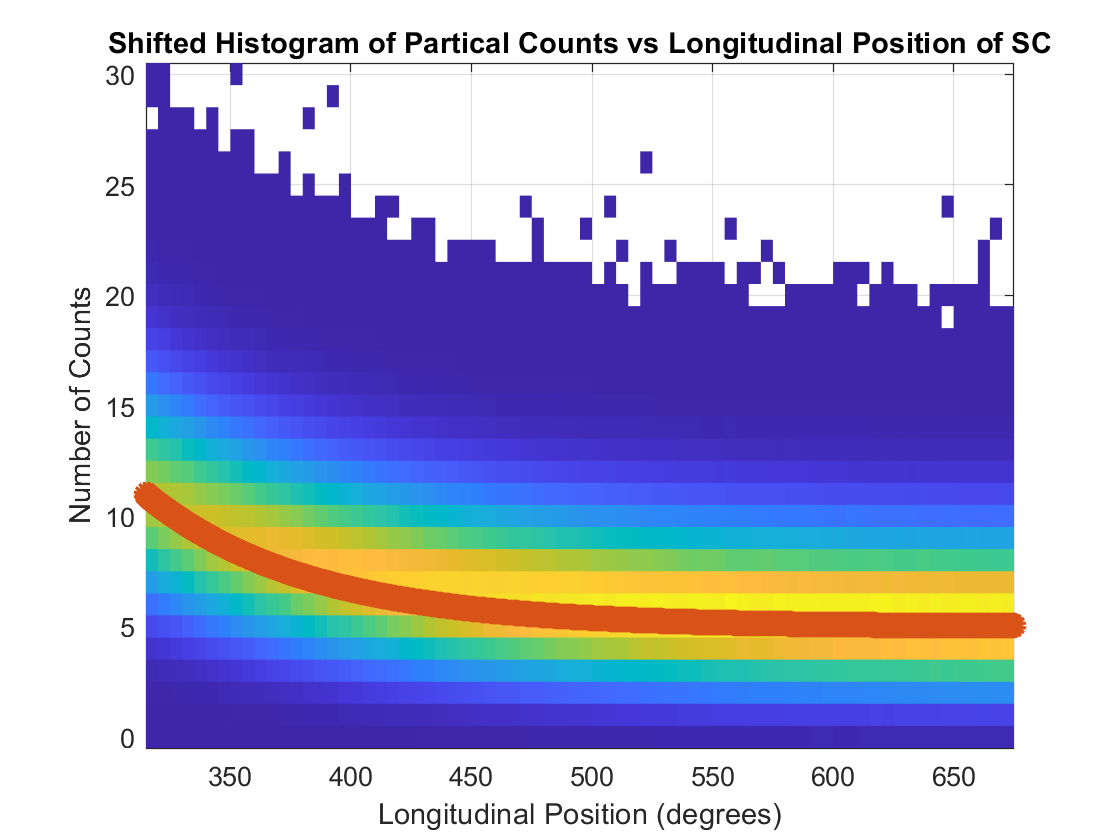

hold off

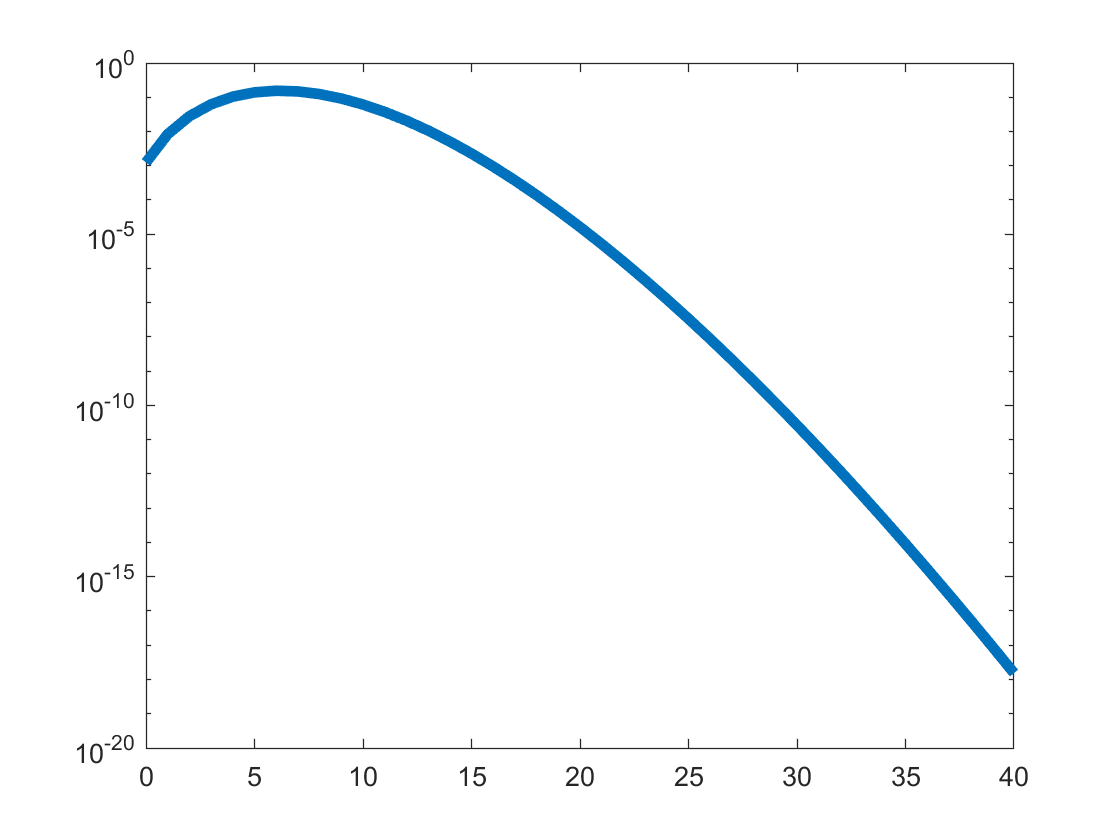

long_val = 400; %choose a value in between 315 and 675
mean_val = mean(long_val);
%mean_val = round(mean_val,10);
x = 0:40;
poisson = makedist("Poisson", 'lambda',mean_val);
semilogy(x,pdf(poisson,x),"LineWidth",4);

function [] = plot_scat(range, x)
% range(start_val, length)
end_pnt = range(1)+range(2);
t = linspace(range(1),end_pnt, range(2));
scatter(t,x(range(1):range(1)+range(2)-1))
end